%RBE501_HW2_2a
%Ali Abdelhamid
clear 
close all
clc

## POE FWD KIN

%M and Slist derrived from robot in home position (all thetas = 0):

syms th1 th2

M = [1,0,0,600;
    0,1,0,0;
    0,0,1,0;
    0,0,0,1];

Slist = [[0;0;1;0;0;0],[0;0;1;0;-300;0]];

thetalist = [th1; th2];

%Iterative loop for deriving array of ES matrixes 
I = eye(3);  %identity matrix
T = {};      %define T as an array to store all ES matrixes

for i = 1 : length(thetalist)
    w = skew(Slist(1:3,i));
    v = Slist(4:6,i);
    theta = thetalist(i);
    
    R = I + sin(theta)*w + (1-cos(theta))*w^2;
    
    star = (I*theta + (1-cos(theta))*w + (theta-sin(theta))*w^2)*v;
    
    T{i} = [R star; 0 0 0 1];
end

T = T{1}*T{2}*M;

## CALCULATING JACOBIAN

p = T(1:3,4);

Jv = jacobian(p,[th1,th2]);

%We will need the inverse jacobian to calculate
invJv = pinv(Jv);

## Plotting trajectory equations [TASK SPACE]

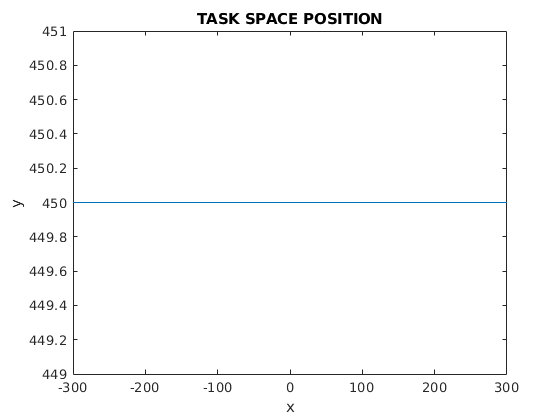

%We start with the task space plots because that will give us the sets of
%data to use in our inverse kinematics when plotting for joint space

syms t

%x
eqx = 300 - 72*(t)^2 + 9.6*(t)^3;
eqx_d = 2*(-72)*(t) + 3*(9.6)*(t)^2;
eqx_dd = 2*(-72) + 6*(9.6)*(t);
%y
eqy = 450;
eqy_d = 0;
eqy_dd = 0;

x = 0:0.1:5;
eqx_set = subs(eqx, t, x);
eqx_d_set = subs(eqx_d, t, x);
eqx_dd_set = subs(eqx_dd, t, x);
eqy_set = subs(eqy, t, x);
eqy_d_set = subs(eqy_d, t, x);
eqy_dd_set = subs(eqy_dd, t, x);

figure (1)
plot(eqx_set,eqy_set)
title('TASK SPACE POSITION')
xlabel('x')
ylabel('y')

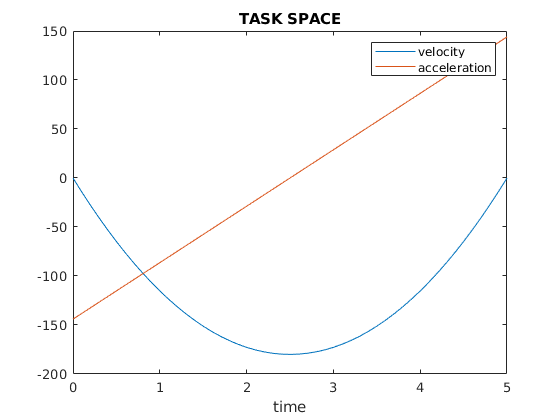

%since y-vel and y-acc are 0, we will plot x-vel and x-acc against time to
%better visualize:
figure(2)
plot(x,eqx_d_set)
hold on
plot(x,eqx_dd_set)
title('TASK SPACE')
legend({'velocity', 'acceleration'})
xlabel('time')

## Solving IK for set of q values

%we know our starting q value with the elbow down configuration at 300,450:
%q1=0.5350, q2=0.8957 that would be a good initial guess out of the loop
%array to store IK-derived q values
q0 = [0; 0];
q_list = zeros(2,length(eqx_set)); 
%qq = q0; %assign q initial to q current (step 2)

qq = q0; %assign q initial to q current (step 2)



for i = 1:length(eqx_set)
    qq = qq(:,1) + [0.5;0.5];
    pd = [eqx_set(i); eqy_set(i); 0]; %Plug in next position

    p_i = subs(p, [th1 th2], qq'); %current/home position of EE
    p_i = double(p_i);

    num_Jv = subs(Jv, [th1 th2], qq');

    err = 10; %calculating error between goal and current

    while err > 1 %1mm accuracy err while loop (step 3)
        delta_q = double(pinv(num_Jv)*(pd-p_i));
        qq = qq+delta_q; %increment q values with result from inverse jacobian
        num_Jv = double(subs(Jv, [th1 th2], qq')); %recalculating new jacobian wrt new qq
        p_i = double(subs(p, [th1 th2], qq'));
        err = double(abs(norm(pd-p_i))); 
    end
    
    %only exits the loop when we find qs and then we save them in q_list
    q_list(:,i)= double(qq);
    
    %Note how we will not be resetting the "initial guess" for q when we
    %exit the loop since this qq value would be the best guess for the next
    %iteration
   
end

## Plotting Joint Space Values given Task Space Trajectory:

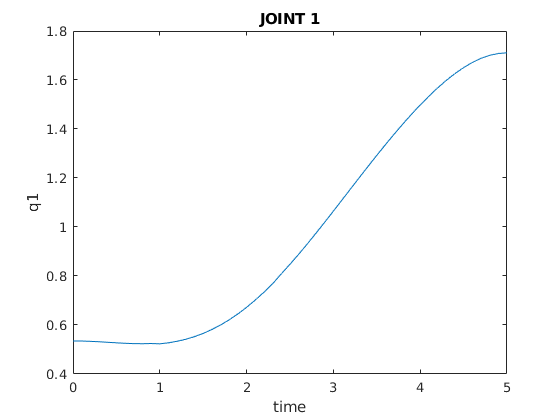

figure (3)
plot(x,q_list(1,:))
title('JOINT 1')
xlabel('time')
ylabel('q1')

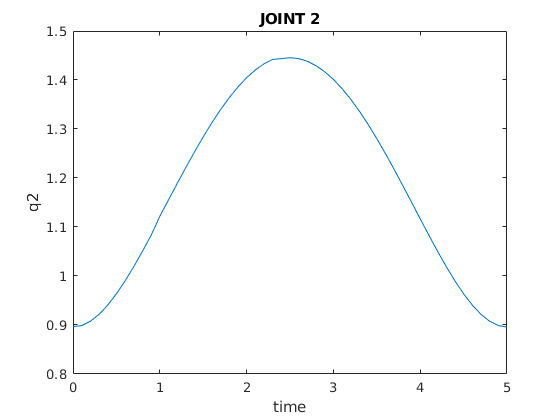

figure (4)
plot(x,q_list(2,:))
title('JOINT 2')
xlabel('time')
ylabel('q2')

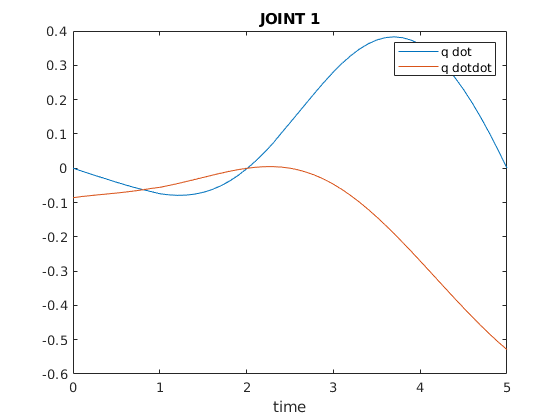


%Now we use the pinv(jacobian) to derive plots for q dot and q dotdot
invJv_1 = subs(invJv(1,1), th1, double(q_list(1,:)));
for j = 1:length(x)
    invJv_11 = double(subs(invJv_1, th2, q_list(2,j)));
end
invJv_1 = subs(invJv(1,2), th1, double(q_list(1,:)));
for j = 1:length(x)
    invJv_12 = double(subs(invJv_1, th2, q_list(2,j)));
end
invJv_2 = subs(invJv(2,1), th1, double(q_list(1,:)));
for j = 1:length(x)
    invJv_21 = double(subs(invJv_2, th2, q_list(2,j)));
end
invJv_2 = subs(invJv(2,2), th1, double(q_list(1,:)));
for j = 1:length(x)
    invJv_22 = double(subs(invJv_2, th2, q_list(2,j)));
end

%qdot = pinv(jacobian)*xdot
q1_d_set = (double(invJv_11).*double(eqx_d_set)) + (double(invJv_12).*double(eqy_d_set));
q2_d_set = (double(invJv_21).*double(eqx_d_set)) + (double(invJv_22).*double(eqy_d_set));
%qdotdot = pinv(jacobian)*xdotdot; time derivative of jacobian is zero
q1_dd_set = (double(invJv_11).*double(eqx_dd_set)) + (double(invJv_12).*double(eqy_dd_set));
q2_dd_set = (double(invJv_21).*double(eqx_dd_set)) + (double(invJv_22).*double(eqy_dd_set));

figure(5)
plot(x,q1_d_set)
hold on
plot(x,q1_dd_set)
title('JOINT 1')
xlabel('time')
legend({'q dot' , 'q dotdot'})

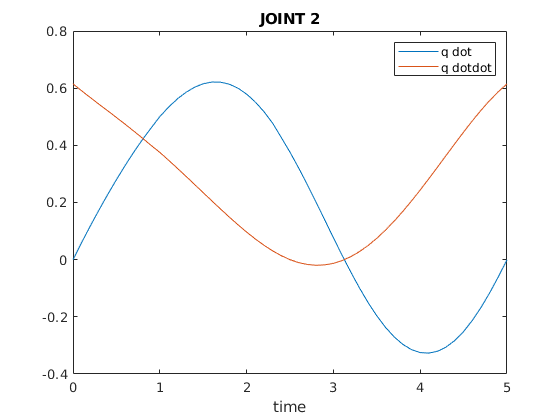


figure(6)
plot(x,q2_d_set)
hold on
plot(x,q2_dd_set)
title('JOINT 2')
xlabel('time')
legend({'q dot' , 'q dotdot'})

## Functions

function skewMatrix = skew(a)
        skewMatrix = [0,-a(3),a(2);
        a(3),0,-a(1);
        -a(2),a(1),0];
end